clear
beta0=10;
beta1=1;
sigma=0.5;
num=10000;
x1=[1 2 3 4 5 6 7 8 9 10];
X1=[ones(1,10);x1]'

X1 =      1     1
     1     2
     1     3
     1     4
     1     5
     1     6
     1     7
     1     8
     1     9
     1    10


x2=[1 1 1 1 1 10 10 10 10 10];
X2=[ones(1,10);x2]'

X2 =      1     1
     1     1
     1     1
     1     1
     1     1
     1    10
     1    10
     1    10
     1    10
     1    10


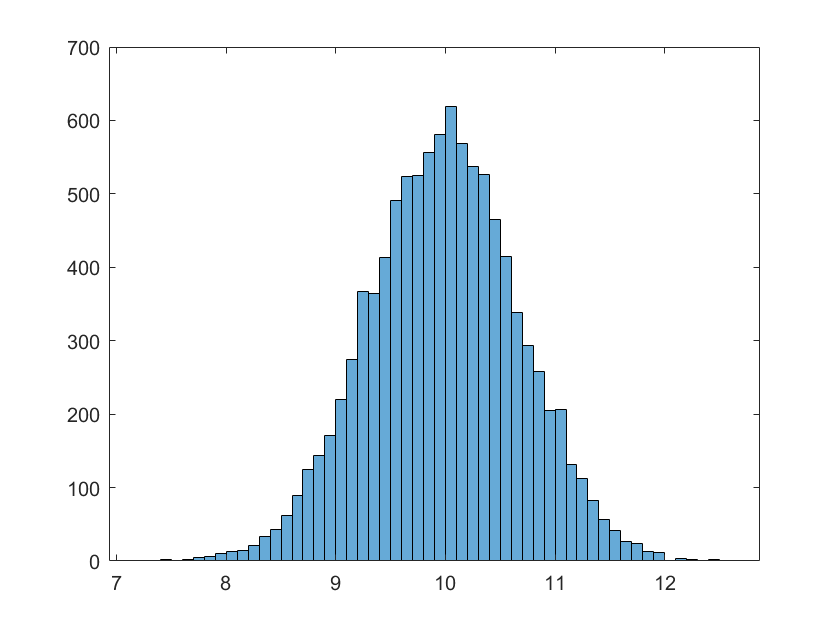

B1=zeros(num,2);
B2=zeros(num,2);
ss1=zeros(num,1);
ss2=zeros(num,1);
for j=1:num
    y2=beta0*1+x2'+randn(10,1);
    y1=beta0*1+x1'+randn(10,1);
    B1(j,:)=inv(X1'*X1)*X1'*y1;
    B2(j,:)=inv(X2'*X2)*X2'*y2;
    ss1(j)=1/9*sum((y1-B1(j,1)-x1'*B1(j,2)).^2);
    ss2(j)=1/9*sum((y2-B2(j,1)-x2'*B2(j,2)).^2);
end

histogram(B1(:,1))

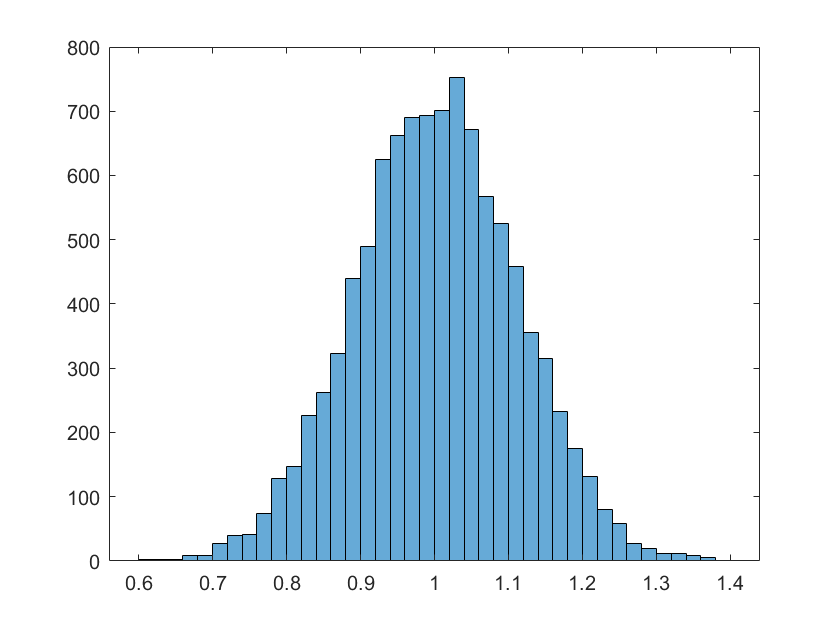

histogram(B1(:,2))

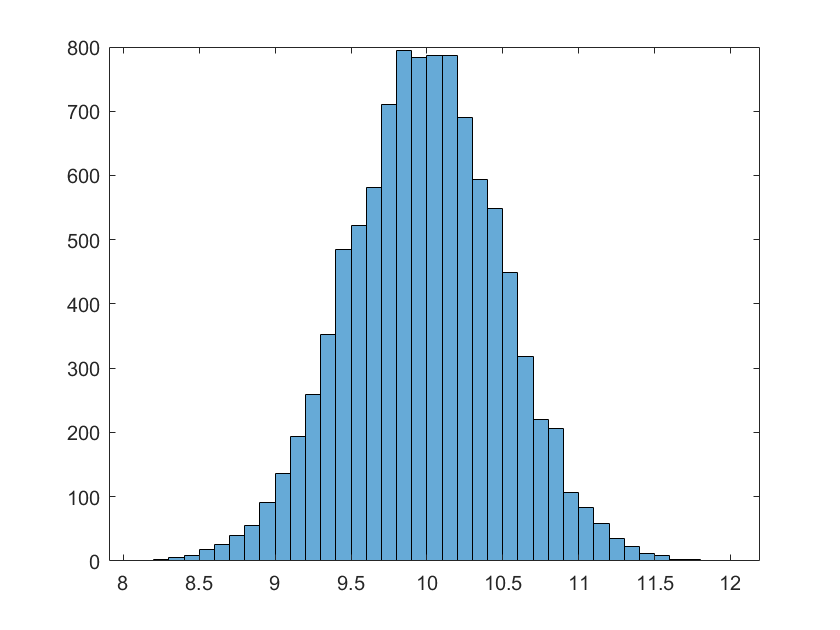

histogram(B2(:,1))

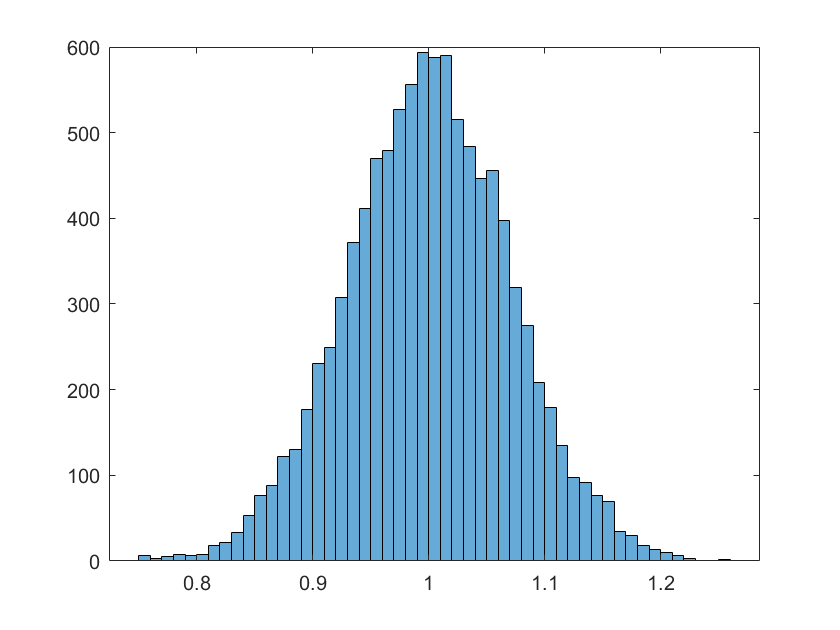

histogram(B2(:,2))

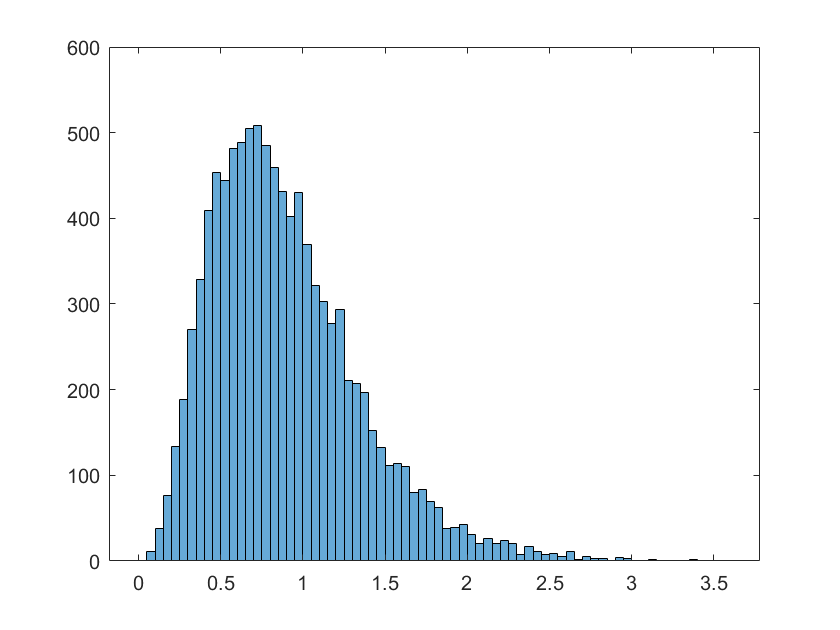

histogram(ss1)

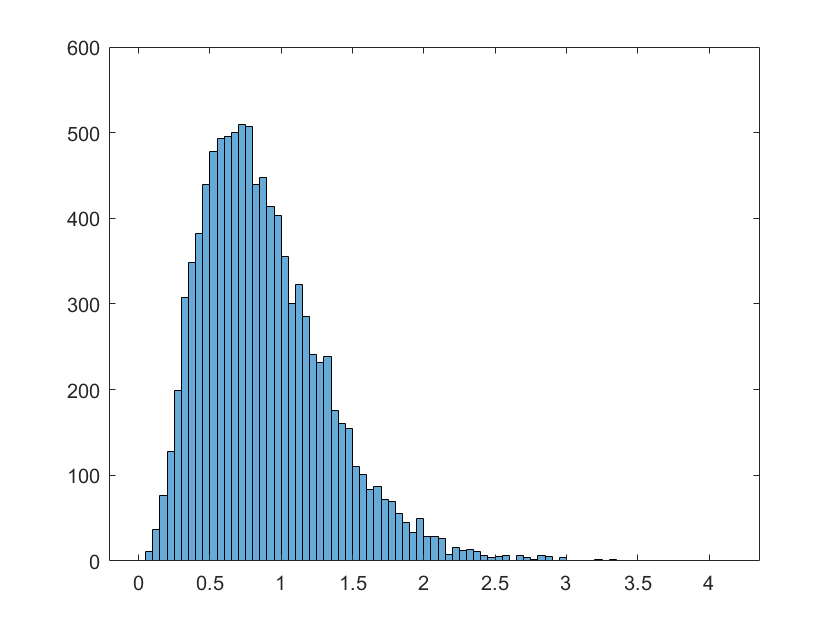

histogram(ss2)


Mean_B10=mean(B1(:,1))

Mean_B10 = 9.9848

Mean_B11=mean(B1(:,2))

Mean_B11 = 1.0027

Mean_B20=mean(B2(:,1))

Mean_B20 = 9.9893

Mean_B21=mean(B1(:,2))

Mean_B21 = 1.0027

Mean_ss1=mean(ss1)

Mean_ss1 = 0.8960

Mean_ss2=mean(ss2)

Mean_ss2 = 0.8857


var_B10=var(B1(:,1))

var_B10 = 0.4673

var_B11=var(B1(:,2))

var_B11 = 0.0120

var_B20=var(B2(:,1))

var_B20 = 0.2523

var_B21=var(B1(:,2))

var_B21 = 0.0120

Var_ss1=var(ss1)

Var_ss1 = 0.2047

Var_ss2=var(ss2)

Var_ss2 = 0.1983

ans =     10    55
    55   385


ss1 =     0.5154
    0.4895
    0.6999
    0.9948
    0.6519
    0.9063
    0.4685
    1.1930
    0.5251
    1.0395


%k1=ss1*inv(X1'*X1)

错误使用  * 
用于矩阵乘法的维度不正确。请检查并确保第一个矩阵中的列数与第二个矩阵中的行数匹配。要执行按元素相乘，请使用 '.*'。

%k2=ss2*inv(X2'*X2)